%Import Raw Data  

USDebt_idx = USDebt(1:24,1:2);
table(USDebt_idx)

ans = 24×1 table
                USDebt_idx             
    ___________________________________

    RecordDate    DebtOutstandingAmount
    __________    _____________________
                                       
    2023-09-30         3.3167e+13      
    2022-09-30         3.0929e+13      
    2021-09-30         2.8429e+13      
    2020-09-30         2.6945e+13      
    2019-09-30         2.2719e+13      
    2018-09-30         2.1516e+13      
    2017-09-30         2.0245e+13      
    2016-09-30         1.9573e+13      
    2015-09-30         1.8151e+13      
    2014-09-30         1.7824e+13      
    2013-09-30         1.6738e+13      
    2012-09-30         1.6066e+13      
    2011-09-30          1.479e+13      
    2010-09-30         1.3562e+13      
    2009-09-30          1.191e+13      
    2008-09-30         1.0025e+13      


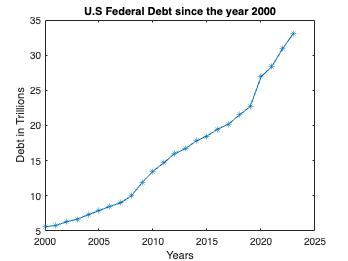


Years = [2000,2001,2002,2003,2004,2005,2006,2007,2008,2009,2010,2011,2012,2013,2014,2015,2016,2017,2018,2019,2020,2021,2022,2023];
Debt = [5.6,5.8,6.3,6.7,7.3,7.9,8.5,9.0,10.0,11.9,13.5,14.7,16.0,16.7,17.8,18.5,19.5,20.2,21.5,22.7,26.9,28.4,30.9,33.1];

%Plot original Data
grid on
plot(Years,Debt,marker="*");
title("U.S Federal Debt since the year 2000", "FontName", "Helvetica","FontAngle","normal","FontWeight","bold")
ylabel("Debt in Trillions", "FontName", "Helvetica","FontAngle","normal","FontWeight","normal")
xlabel("Years", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")


%Create a Fittype for the Curve
fitType = fittype('a*x^2 + b*x + c');

%Apply the Fittpe
fitObject = fit(Years',Debt',fitType);


x_additional = 2023:2033;
y_additional = feval(fitObject, x_additional);

%Plot Prediction
plot(x_additional, y_additional, 'x', 'Color', 'r');
xlabel('Year');
ylabel('Federal Debt (trillions of dollars)');
title('Current US Federal Debt with Predicition');
legend('Data','Fitted Curve','Predicted Trend');

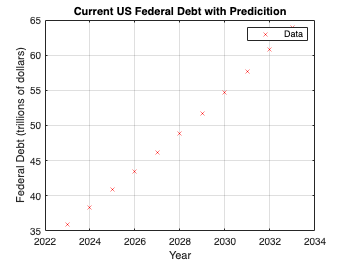


grid on;